**Faça um programa MatLab, que peça para introduzir os coeficientes de dois polinômios e apresente os seguintes resultados:**

**a) As raízes de cada um dos polinômios**

**b) Gráfico de cada um dos polinômios**

**c) Divisão dos polinômios**

**d) Expansão em frações parciais da relação dos polinômios**

Introduza os coeficientes do polinomio 1 


Introduza os coeficientes do polinomio 2 


As raízes do polinomio 1 são: 



r_x =

  0×1 empty double column vector



As raízes do polinomio 2 são: 



r_y =

  0×1 empty double column vector



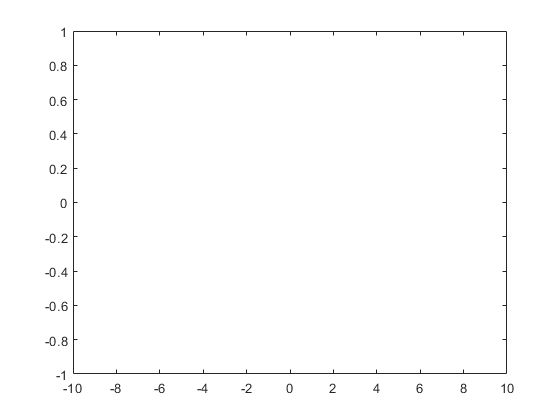

clc

clear all
close all

Grau = input('Digite o grau do polinomio 1: ');
x = zeros(0,Grau+1);
fprintf('Introduza os coeficientes do polinomio 1 \n')
for i = 1:1:(Grau+1)
    x(1,i) = input('');
end

grau = input('Digite o grau do polinomio 2: ');
y = zeros(0,grau+1);
fprintf('Introduza os coeficientes do polinomio 2 \n')
for i = 1:1:(grau+1)
    y(1,i) = input('');
end

%%%%%%%%%%%%%%%%%% LETRA A %%%%%%%%%%%%%%%%%%%%%%%%%%%
fprintf('As raízes do polinomio 1 são: \n');
r_x = roots(x)
fprintf('As raízes do polinomio 2 são: \n');
r_y = roots(y)

%%%%%%%%%%%%%%%%%% LETRA B %%%%%%%%%%%%%%%%%%%%%%%%%%%
passo = -10:0.001:10;
x1 = polyval(x,passo);
y1 = polyval(y,passo);
plot(passo,x1,'k',passo,y1,'b');
axis([-5,5,-5,5]);
legend('Polinômio 1', 'Polinômio 2'); 
xlabel('Eixo x'); ylabel('Eixo y');
title('Gráfico de cada um dos polinômios')
grid on

%%%%%%%%%%%%%%%%%% LETRA C %%%%%%%%%%%%%%%%%%%%%%%%%%%
if length(x) == length(y)
    fprintf('A divisão do polinômio 1 pelo polinômio 2 é:')
    d1 = x./y
    fprintf('A divisão do polinômio 2 pelo polinômio 1 é:')
    d2 = y./x
else
    fprintf('Não é possível realizar a divisão dos polinômio');
end
    
